Paper implementation 

**Telomere end replicaiton Problem and Cell Aging (Michael Z Levy, 1992)**

Passive Incomplete Replicaiton model for telomere loss (Probabilistic model)

deletions = 0:1:100;
gen = 200; % Generation
dis = 101; % no. of delitions
pr = zeros(gen,dis); % Initializing an empty matrix for Probability
dist = zeros(gen,dis); % Empty Matrix for distribution of deletion
for n=1:gen
    for d=0:dis-1
        if(d<=(n+1)/2)
            dist(n,d+1) = exp( gammaln(n+2)-gammaln(2*d+1)-gammaln(n+1-2*d+1));
            %pr(n,d+1) = nchoosek(n+1,2*d)/(2^n);
            pr(n,d+1) = exp( gammaln(n+2)-gammaln(2*d+1)-gammaln(n+1-2*d+1))/(2^n);
        end
    end
end

% Alternative method to find binomial coefficients nchoosek(n,j)
%exp( gammaln(n+1)-gammaln(j+1)-gammaln(n-j+1) )

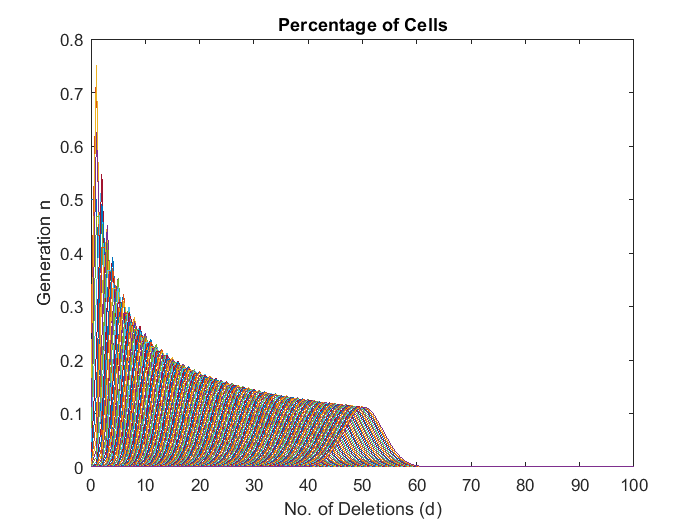


figure(1);
plot(deletions,pr);
xlabel('No. of Deletions (d)');
ylabel('Generation n');
title('Percentage of Cells');

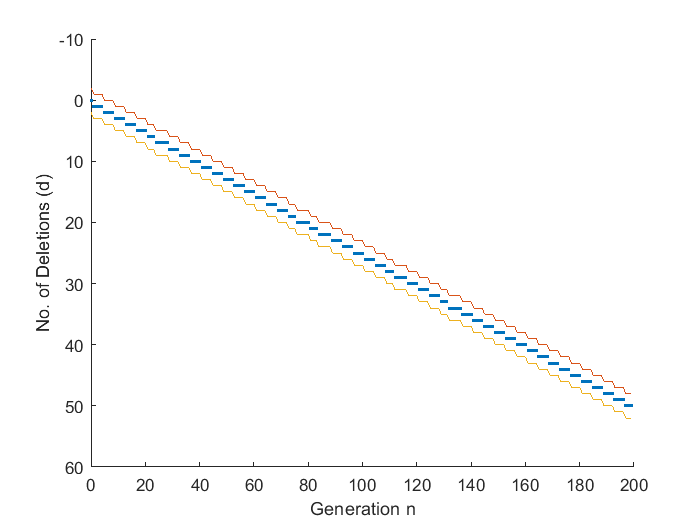

Max_Del = zeros(gen,1); % Max prob of no. of deletions each generations
M = 0; I = 0;
SDL = zeros(gen,1);
SDR = zeros(gen,1);
for i = 1:n
    [M,I] = max(pr(i,:));
    Max_Del(i) = I-1;
    SDL(i) = I-3;
    SDR(i) = I+1;
end
% [M,I] = max(sum(pr));
% Del = I-1;
G = 0:1:gen-1; % Represent generation
figure(2); hold on;
%plot(G,Max_Del);
scatter(G,Max_Del,'.');
plot(G,SDL);
plot(G,SDR);
ylabel('No. of Deletions (d)');
xlabel('Generation n');
set(gca,'Ydir','reverse');

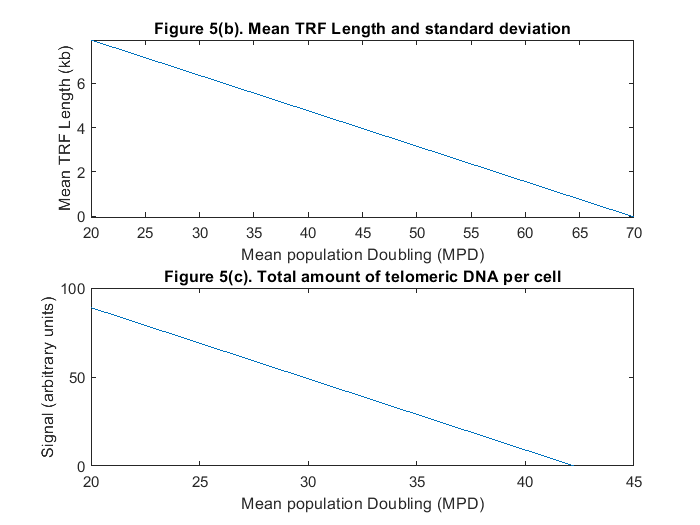

% After every four generations mean length decreased one full deletions.
%% 5(b) Mean TRF Length and standard deviation of the distribution
% 5(c) Total amount of telomeric DNA per cell

% Non TTAGGG portion of TRF
% TRF - T = 8kb - 90*(0.04)kb ~ 4kb 
%length_nonTTAGGC = TRF - T; % length of non TTAGGA portion
% Mean length of telomeric DNA (TTAGGC) is 4kb less than length of TRF

% Mean population doubling
MPD = 20:0.25:70;
Signal = 0:10:70;
m_TRF = 0:1:12; % Mean TRF length (kb)
c = 0.04; % Scaling factor 

%TRF = -0.04 * gen + 8;
%T = -1*c*gen + 90*c ;
TRF = []; % TRF(Terminal Restriction fragment empty array)
T = []; % Telomeres empty array
Sig = []; % Signal empty array
for i=1:n+1
    TRF(i) = -0.04*i + 8;
    T(i) = -1*c*i + 90*c ;
    Sig(i) = -i + 90;

end

figure(5);
subplot(2,1,1);
plot(MPD,TRF);
xlabel('Mean population Doubling (MPD)');
ylabel('Mean TRF Length (kb)');
title('Figure 5(b). Mean TRF Length and standard deviation');
subplot(2,1,2);
plot(MPD,Sig);
xlabel('Mean population Doubling (MPD)');
ylabel('Signal (arbitrary units)');
ylim([0 100]);
title('Figure 5(c). Total amount of telomeric DNA per cell');

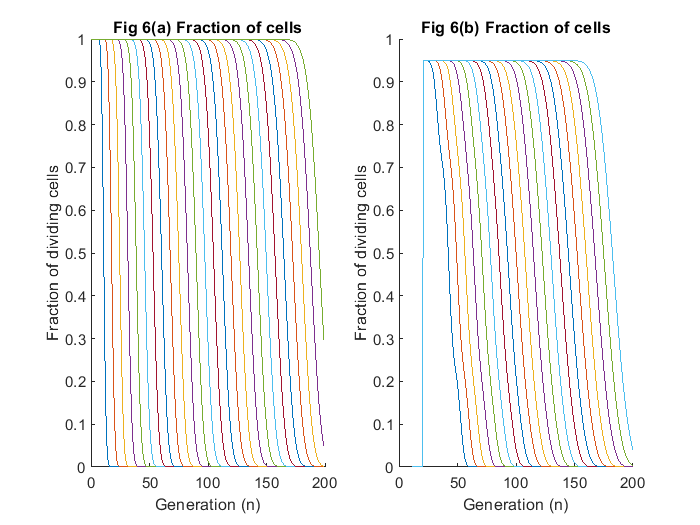

%% 6(a) Fraction of dividing cells.

% (b) Replicative senescence
% Probability P(d_c,n) that at gen. n no checkpoint signal is triggered by 
% telomere is summations of all probabilities p(n,d) d<d_c

% Example case for gen 5 and d_c = 3;
%critical deletion
d_c = 5;
%Pr_dc = sum(pr(5,1:d_c));
Pr_dc = [];
for i=1:2:gen
    Pr_dc(i) = sum(pr(i,1:d_c));
end

% Fraction of dividing cells at gen. n
k = 10 ; % no. of chromosomes with short telomeres

% F_dc = [];
% for i=1:n
%     F_dc = Pr_dc^k;
% end



Pr_dc = [];
F_dc = [];
k=10;

figure(6);
subplot(1,2,1);
title('Fig 6(a) Fraction of cells');
xlabel('Generation (n)');
ylabel('Fraction of dividing cells');
ylim([0 1]);
hold on;
for d_c=5:2:55
    for i=1:n
        Pr_dc(i) = sum(pr(i,1:d_c));
        F_dc(i) = Pr_dc(i)^k;
    end
    plot(G,F_dc);
end

% Fig 6(b)
subplot(1,2,2);
title('Fig 6(b) Fraction of cells');
xlabel('Generation (n)');
ylabel('Fraction of dividing cells');
hold on;
Fdt = [];
G_u = 11:200;
for d_c=11:2:49
    for i=1:n
        Pr_dc(i) = sum(pr(i,1:d_c));
        F_dc(i) = Pr_dc(i)^k;
    end
    for j=11:n-10
        Fdt(j) = 0.95*(0.25*F_dc(j-10) + 0.5*F_dc(j) + 0.25*F_dc(j+10));
    end
    plot(G_u,Fdt);
end